# Example 1

#### Problem OCP:


$$\min_{{x}(t),{u}(t),t_f} \int_0^{t_f} 1 d \tau $$


subject to:


$$
 \dot{{x}}(t) = u(t), \quad {x}(0)=3 \quad {x}(t_f)=0 \quad u(t) \leq v_{\max}   \quad -u(t) \leq -v_{\min}.   
$$


## Implementation:

clear all
close all

### Load Parameters

CONSTANTS.N = 5; % Order of approximation
CONSTANTS.vmax = 5;
CONSTANTS.vmin = -5;
CONSTANTS.x0 = 3;
CONSTANTS.xf = 0;

### Initial Guess

N = CONSTANTS.N;
%x1 = linspace(CONSTANTS.x0,CONSTANTS.xf,CONSTANTS.N+1)';
x1 = ones(N+1,1);
u1 = ones(N+1,1);
tf = 5;
x0 = [x1;u1;tf];

### Linear Constraints and UL bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

### Optimize (fmincon)

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',300000);
tic
[x,f] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 0.140419 seconds.


### Plot

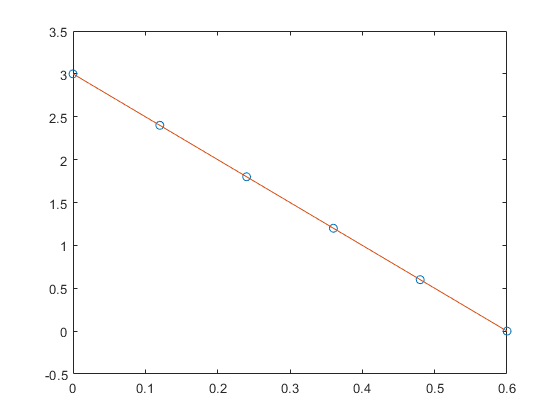

N = CONSTANTS.N;
x1 = x(1:N+1);
u1 = x(N+2:2*N+2);
tf = x(end);

[tnodes,w,Diff] = BeBOT(N,tf);
t = 0:0.001:tf;

figure
plot(tnodes,x1,'o'); hold on
plot(t,BernsteinPoly(x1',t));

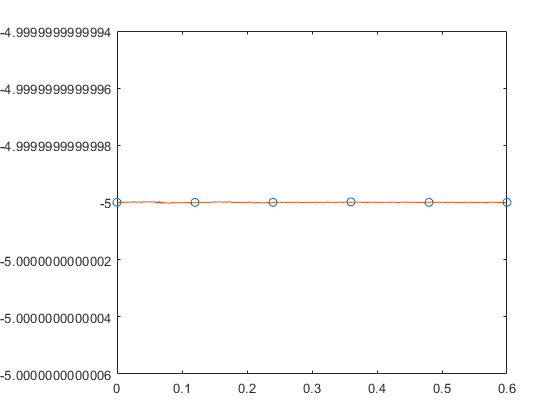

figure
plot(tnodes,u1,'o'); hold on
plot(t,BernsteinPoly(u1',t));

### Cost function

function J = costfun(x,CONSTANTS)
N = CONSTANTS.N; 

x1 = x(1:N+1);
u1 = x(N+2:2*N+2);
tf = x(end);

J = tf;
end

### Nonlinear Constraint

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N; 

x1 = x(1:N+1);
u1 = x(N+2:2*N+2);
tf = x(end);

[tnodes,w,Diff] = BeBOT(CONSTANTS.N,tf);

dyn = x1'*Diff-u1';

nonlcon1 = u1' - CONSTANTS.vmax;
nonlcon2 = -u1' + CONSTANTS.vmin;
 
c=[nonlcon1'; nonlcon2';];
ceq=[dyn'; x1(1)-CONSTANTS.x0; x1(end)-CONSTANTS.xf;];
end